#### Phase 3: Load attached to the biffurcation

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Three_Pipes
r_sensor=2 mm
Q_inlet_CNN=5 uL/min
height_pipe=36 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s


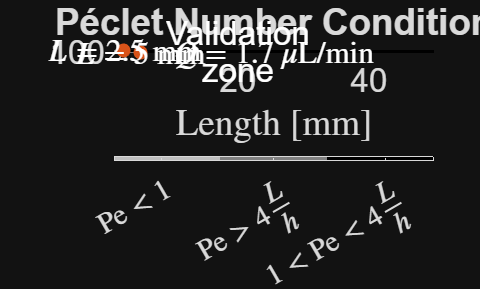

ans = 26.1799

w_Pipe_min=942.4778 um
w_Pipe_min=1 mm


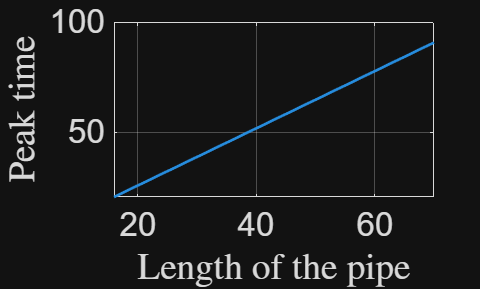

L_1 = 0.0160

L_2 = 0.0307

L_3 = 0.0465

    branch      L_m         Q_m3s          v_ms         Pe       Deff_m2s     t_pred_s    t_target_s
    ______    ________    __________    __________    ______    __________    ________    __________

      1       0.020289    3.6471e-11     0.0010131     74.43    1.4063e-08       20           20    
      2       0.028684    2.5797e-11    0.00071659    52.647    7.2807e-09       40           40    
      3       0.035126    2.1066e-11    0.00058515    42.991    5.0181e-09       60           60    



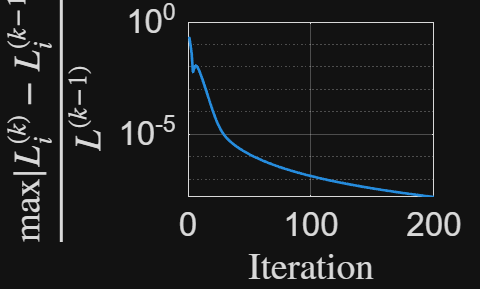

V_sensor/V_CNN =14.9423 %


v_char = 7.7160e-04

Pe = 56.6893

D_eff = 8.3635e-09

v_char = 7.7160e-04

Pe = 56.6893

D_eff = 8.3635e-09

v_char = 7.7160e-04

Pe = 56.6893

D_eff = 8.3635e-09

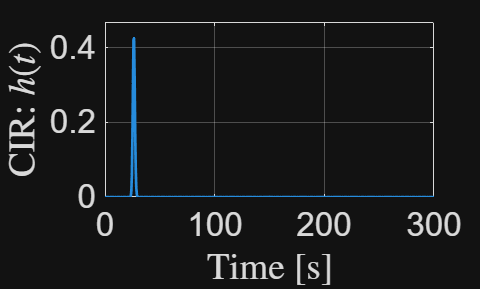

w_0=98.99500000 umL_0=0.21000000 mm

Pu311_x = -2.5872e-04

Pu333_x = 0.0205

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Three_Pipes
r_sensor=2 mm
Q_inlet_CNN=5 uL/min
height_pipe=36 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s


time_delta = 0.0100

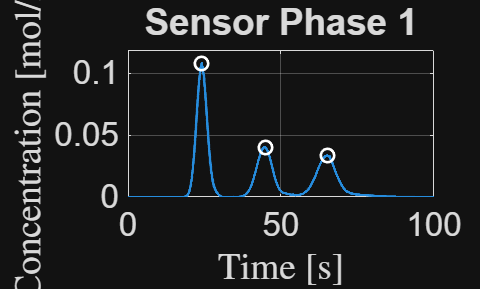

time_delta = 0.0100

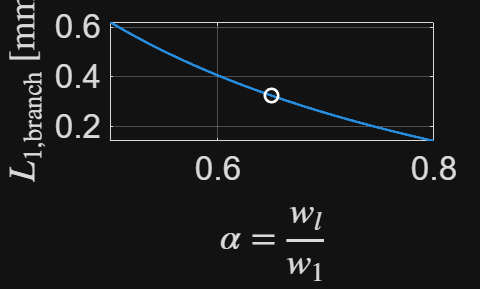

w_0=98.99500000 umL_0=0.21000000 mm

Pb33_x = 0.0193

Pu311_x = -2.5872e-04

Pu333_x = 0.0205

Synthesis_Three_Pipes_Phase_2


%Main parameters
alpha_outlet=0.65; % reduces the width of the connected load to Pipe 1, the less the value, the highest the concentration towards the Sensor
                  % This value is found aiming to control the a amplitude of peak 1 in COMSOL

% 2. Define the rotation angle of the square patch in degrees

time_delta = 0.0100

alpha_deg = -35; 

#### Load CNN

%Loading the area evaluated at COMSOL
% Specify the CSV file
csvFileName = 'area_reactor.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
Table_area=readtable(csvFileName,opts);
area_reactor=(Table_area.Var1(2));

% Specify the CSV file
csvFileName = 'area_sensor.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
Table_area=readtable(csvFileName,opts);
area_sensor=(Table_area.Var1(2));

% Specify the CSV file
csvFileName = 'width_inlet_reactor.csv'; %width of the inlet reactor from the CNN
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
Table_area=readtable(csvFileName,opts);
width_inlet_reactor=str2double(cell2mat(Table_area.Var1(3)));
width=alpha_outlet*width_inlet_reactor;

% Specify the CSV file
csvFileName = 'width_inlet_2_reactor.csv';%width of the inlet to the reactor from the top
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
Table_area=readtable(csvFileName,opts);
width_2=str2double(cell2mat(Table_area.Var1(3)));


% Specify the CSV file
csvFileName = 'area_Inlet_Reactor.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
Table_area=readtable(csvFileName,opts);
area_Inlet_Reactor=str2double(cell2mat(Table_area.Var1(3)));


%Po2
% Po2=Pb12;

%Po1
% Po1=Pb12- [0 length_inlet_reactor];


%Po1
% Po1=[Pb12(1) (Pb11(2)+Pb12(2))/2];
Po1=Pb13;

% %evaluating the line Pb32 to Pb33
% m=(Pb33(2)-Pb32(2))/(Pb33(1)-Pb32(1));
% %evaluating the line at x=Pb14(1)
% x=Po1(1);
% y=m*(x-Pb32(1))+Pb32(2);
% y=length_inlet_reactor;
% %Po2
% Po2=[x (y+Pb12(2))/2];
Po2=Po1+[0 width];

%Po3
%evaluating the area to cover by the outlet
%height of the rectangle
b=Po2(2)-Po1(2);
%width of the rectangle
a=L_1/2;
a=area_reactor/width;
Po3=[Po2(1)-a Po2(2)];

%Po4
Po4=[Po3(1) Po1(2)];

%Evaluating the remanent area
area_rem=area_reactor-a*b

area_rem = -1.0588e-22

%Evaluating the side of the square
a_square=sqrt(area_rem);
a_square=sqrt(area_sensor);
%Po5
Po5=Po4-[a_square 0];

%Po6
Po6=Po5+[0 a_square];

%Po7
Po7=Po4+[0 a_square];

Po7_x=Po7(1);
Po7_y=Po7(2);

Po6_x=Po6(1);
Po6_y=Po6(2);

%Inlet
length_inlet=area_Inlet_Reactor/width

length_inlet = 0.0048

Pinlet_1=Po2-[length_inlet 0];
Pinlet_2=Pinlet_1-[width_2 0];

Pinlet_1_x=Pinlet_1(1);
Pinlet_1_y=Pinlet_1(2);
Pinlet_2_x=Pinlet_2(1);
Pinlet_2_y=Pinlet_2(2);

%Pipe 1 Load polygon
% Stack all vertices row by row
coords = [Po1; Po2; Po3; Po7; Po6; Po5; Po1];
%saving in the CSV file
outputFile = fullfile(pwd, 'datasets', 'pipe_1_load_Phase_3.csv'); % build full path safely
writematrix(coords, outputFile);

%Rotating the points

% Combine the four points into a matrix (4x2)
Points_square = [Po4; Po5; Po6; Po7];

% 2. Define the rotation angle in degrees
alpha_rad = deg2rad(alpha_deg); % Convert to radians

% 3. Find the center of the points
center = mean(Points_square);

% 4. Create the Clockwise Rotation Matrix
% Note: For counter-clockwise, swap the signs on the sine terms
R = [cos(alpha_rad)  sin(alpha_rad); 
    -sin(alpha_rad)  cos(alpha_rad)];

% 5. Perform the rotation
% Subtract center -> Rotate -> Add center back
PointsRotated = (Points_square - center) * R + center;

% 6. Extract back to individual vectors if needed
Po4_new = PointsRotated(1, :);
Po5_new = PointsRotated(2, :);
Po6_new = PointsRotated(3, :);
Po7_new = PointsRotated(4, :);

% 7. Displace towards Po4
dist_vector=Po4-Po4_new;
PointsRotated= PointsRotated+dist_vector;

% 8. Extract back to individual vectors if needed
Po4_new = PointsRotated(1, :);
Po5_new = PointsRotated(2, :);
Po6_new = PointsRotated(3, :);
Po7_new = PointsRotated(4, :);

%To evaluate thet outle coordinates
Po7_new_x=Po7_new(1);
Po7_new_y=Po7_new(2);

Po6_new_x=Po6_new(1);
Po6_new_y=Po6_new(2);

%Pipe 1 Load polygon
% Stack all vertices row by row
coords = [Po1; Po2; Po3; Po7_new; Po6_new; Po5_new; Po4];
%saving in the CSV file
outputFile = fullfile(pwd, 'datasets', 'pipe_1_load_Phase_3.csv'); % build full path safely
writematrix(coords, outputFile);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Po7_new_x, "m", "Po7_new_x");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Po7_new_y, "m", "Po7_new_y");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Po6_new_x, "m", "Po6_new_x");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Po6_new_y, "m", "Po6_new_y");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pinlet_1_x, "m", "Pinlet_1_x");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pinlet_1_y, "m", "Pinlet_1_y");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pinlet_2_x, "m", "Pinlet_2_x");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pinlet_2_y, "m", "Pinlet_2_y");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

%===============Helpers========================

function writeComsolParamCSV(filename, T)
    % Writes the 3-column cell array back to CSV
    writetable(T, filename, "Delimiter", ",","WriteVariableNames", false);
end


function T = upsertParamFromVar(T, var, unit, desc)
%UPSERTPARAMFROMVAR Upsert a COMSOL parameter row using MATLAB variable name.
%
% Usage:
%   T = upsertParamFromVar(T, myVar, "mol/m^3", "Description");
%   T = upsertParamFromVar(T, myVar, "",        "Description");  % no unit

    name = inputname(2);
    if isempty(name)
        error("upsertParamFromVar: Could not infer variable name. Use upsertParamTable with explicit name.");
    end

    % If unit is omitted or passed as empty, treat as no-unit
    if nargin < 3 || isempty(unit) || (isstring(unit) && strlength(unit)==0) || ...
                     (ischar(unit) && strlength(string(unit))==0)
        unit = "";
    end

    % Desc can be omitted too
    if nargin < 4 || isempty(desc)
        desc = "";
    end

    T = upsertParamTable(T, string(name), var, unit, desc);
end


function T = upsertParamTable(T, name, value, unit, desc)
%UPSERTPARAMTABLE Insert or overwrite a parameter row (name, expr, desc)
% in a 3-column table T.

    name = string(name);

    % Normalize unit/desc robustly
    unit = normalizeTextScalar(unit);
    desc = normalizeTextScalar(desc);

    expr = buildComsolExpr(value, unit);

    % Find existing entry in first column
    idx = find(string(T{:,1}) == name, 1, "first");

    if isempty(idx)
        % Append new row (assign all columns)
        newRow = {name, expr, desc};
        T = [T; cell2table(newRow, "VariableNames", T.Properties.VariableNames)];
    else
        % Overwrite existing row
        T{idx,1} = name;
        T{idx,2} = expr;
        T{idx,3} = desc;
    end
end


function expr = buildComsolExpr(value, unit)
%BUILDCOMSOLPR Build "value[unit]" or "value" if unit is empty.

    unit = normalizeTextScalar(unit); % ensures "" if empty/whitespace/etc.

    if isnumeric(value)
        if ~isscalar(value)
            error("buildComsolExpr: value must be scalar for COMSOL parameters.");
        end
        valStr = string(num2str(value, "%.15g"));
    else
        valStr = string(value); % keep expressions as text
    end

    if strlength(unit) == 0
        expr = valStr;
    else
        expr = valStr + "[" + unit + "]";
    end
end


function s = normalizeTextScalar(x)
%NORMALIZETEXTSCALAR Convert x to a clean string scalar.
% - [] / missing / whitespace-only -> ""
% - char/string -> trimmed string scalar

    if nargin == 0 || isempty(x)
        s = "";
        return;
    end

    % Handle missing string
    if isstring(x) && isscalar(x) && ismissing(x)
        s = "";
        return;
    end

    s = string(x);
    if numel(s) ~= 1
        error("Expected a single unit/description text value, got %d elements.", numel(s));
    end

    s = strtrim(s);
    if ismissing(s)
        s = "";
    end
end